# Data Analytics - Load Forecasting Case Study

The amount of electricity required to support an electric grid, also referred to as the "load" on the grid, varies signifcantly over the course of a day.  An example of the load on the grid in downtown New York City is given in Figure 1.

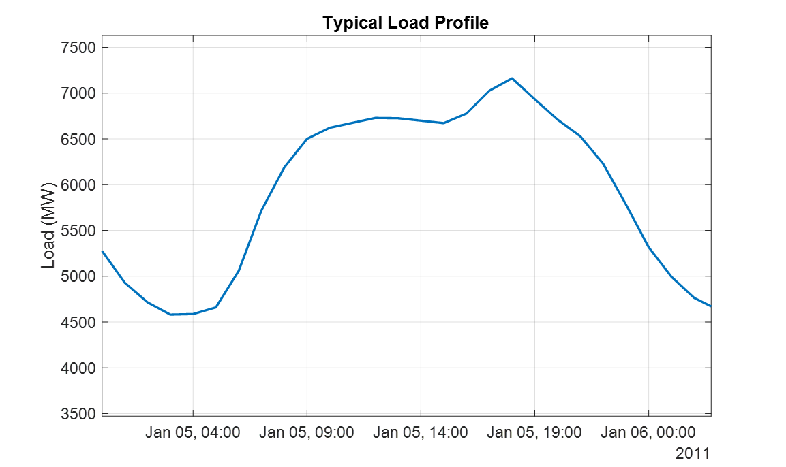

*                                                                Figure 1: Example Load Profile*

The load on the grid varies based on a very large number of factors. Some of the most significant are:

    * **Time of Day**: More electricity is used at times when people are most active

    * **Weather: **More electricity is used during the warmer months, due to air-conditioning units

Having a forecast of the electrical load is important to a number of people.  It helps utility companies plan how much electricity their power plants will need to produce.  It also helps energy traders gain insight into upcoming market dynamics.

To make load forecasts available to these people, we wish to build a web application where users can select a region of interest and get the corresponding load forecast.  Skipping ahead to the final product, here's what we're trying to build:

- [SpotFire Dashboard](http://spotfire-00-ah.mathworks.com/SpotfireWeb/ViewAnalysis.aspx?file=New_LoadForecasting&waid=f6fcdbd36ae9f32e46e92-282308190ffe04)

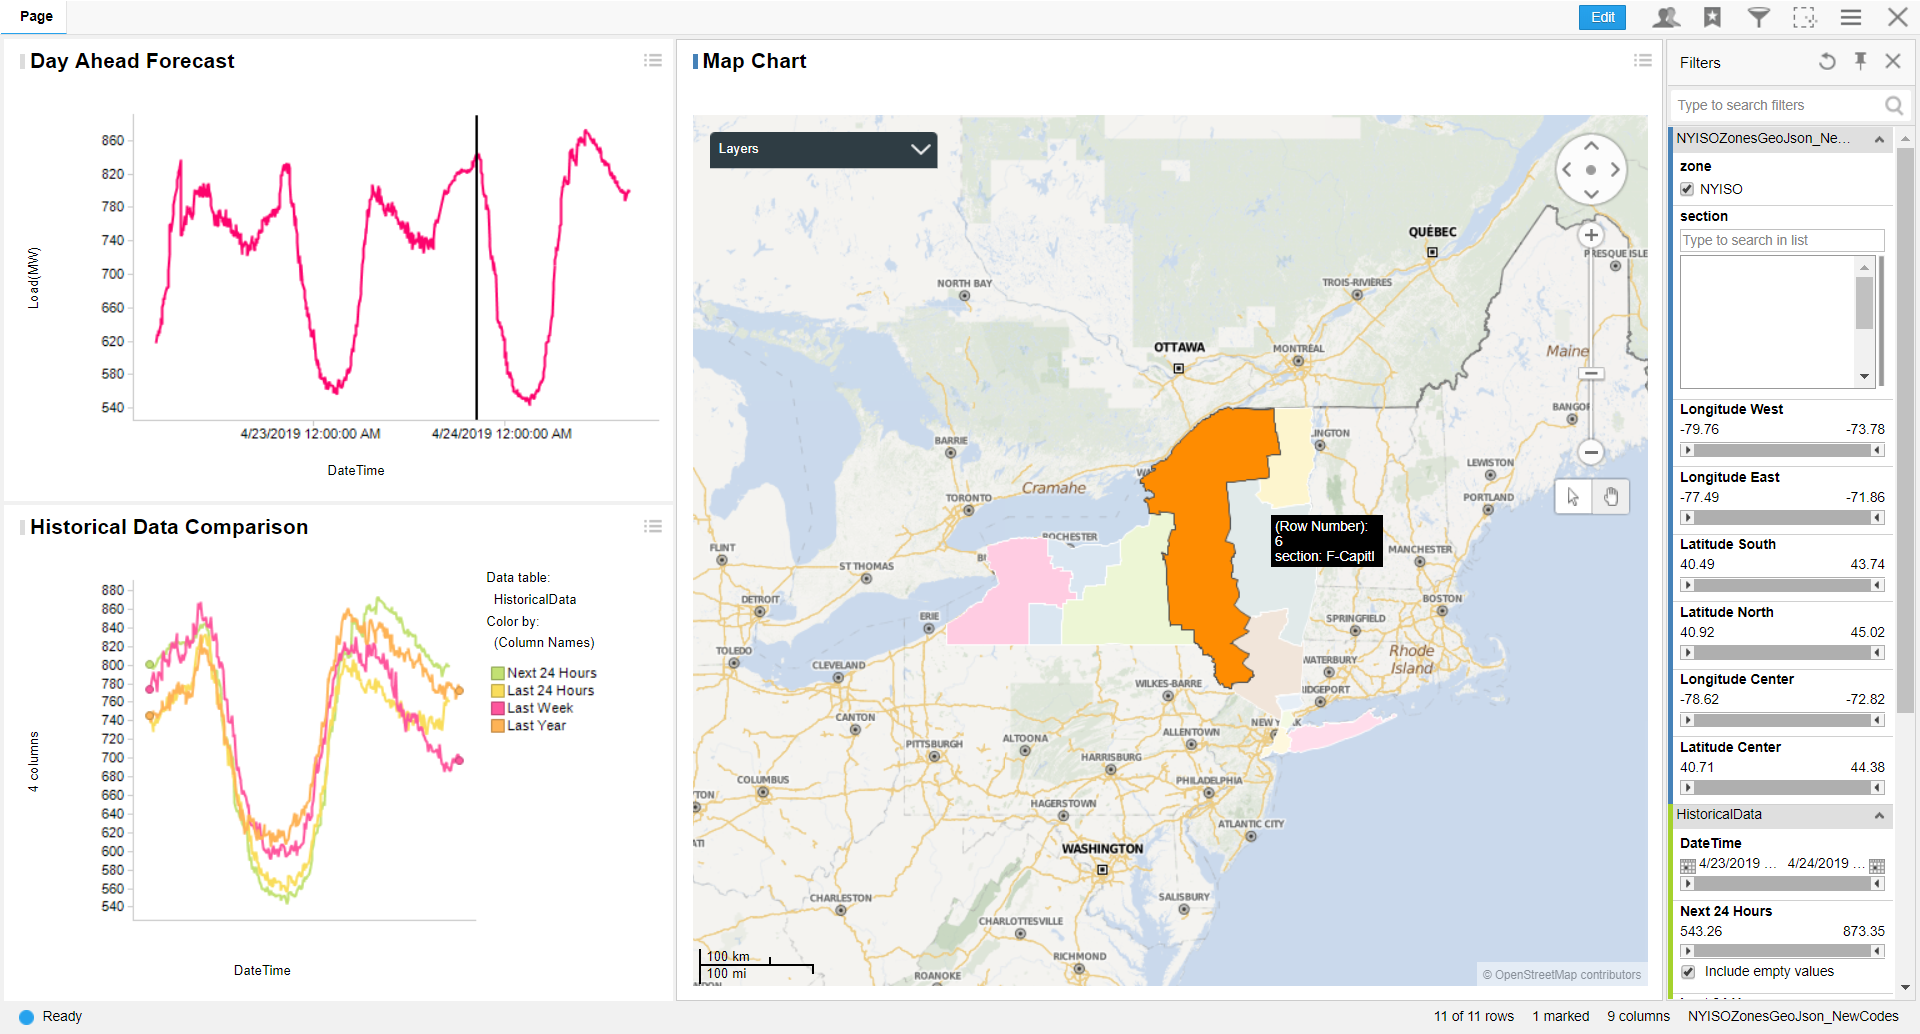

- [Load Forecast Web App](http://ec2-54-165-201-58.compute-1.amazonaws.com:8080/DemandForecastWeb/demandForecast.jsp)

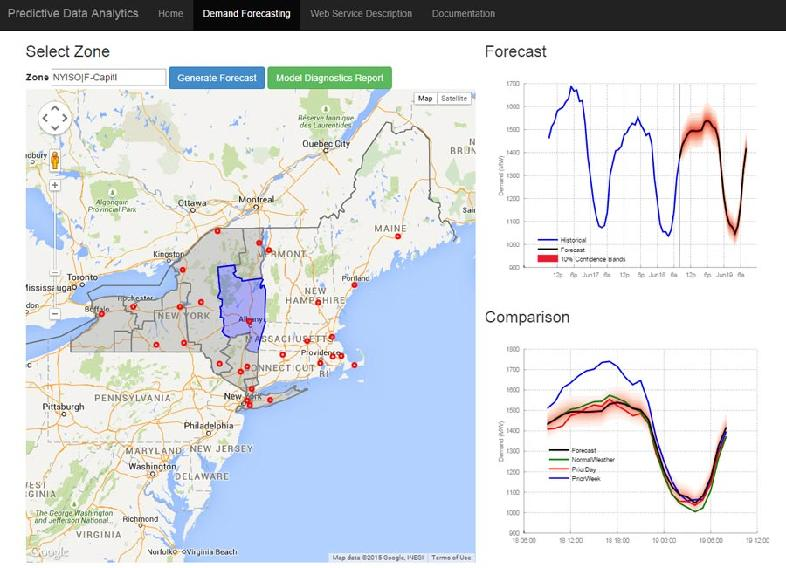

This script covers the workflow used to:

**    * Access historical load and weather data**

**    * Clean and preprocess data**

**    * Merge data from multiple sources**

**    * Perform time-series modeling to extract important predictors**

**    * Train a machine learning model to make predictions about future load**

 It combines shortened versions of Script1-Script8, also included in this directory.

Project information

prj = currentProject;
downloadfolder = fullfile(prj.RootFolder, "DownloadedData");

## Download historical load data

This public dataset is available from the [New York ISO](http://mis.nyiso.com/public) under the 'Real-Time Actual Load' directory.

Create a range of months that we would like data for.

dates = datetime('2005-Feb-01', 'Format', 'yyyyMMdd'):calmonths(1):datetime('2006-Jan-01');
dates = string(dates);
filedestination = fullfile(downloadfolder, "NYISO", "HistLoad" + dates + ".csv.zip");

Download the files.  Since there are several files that need to be downloaded, use the `parfor` construct to have downloads proceed in parallel.

numdates = length(dates);
parfor ii = 1:numdates
    filename = dates(ii) + "pal_csv.zip";
    url = "http://mis.nyiso.com/public/csv/pal/" + filename;    
    disp("Downloading " + ii + " of " + numdates + ". --> " + filename)
    websave(filedestination(ii), url);
end

Starting parallel pool (parpool) using the 'local' profile ...
Connected to the parallel pool (number of workers: 4).


Unzip the files.

for ii = 1:length(dates)
    unzip(filedestination(ii), fullfile(downloadfolder, "NYISO", "HistLoad"))
end

## Aggregate files

What do raw files look like? Print out the first five lines with line numbers.

d = dir(fullfile(downloadfolder, "NYISO", "HistLoad\*.csv"));
dbtype(fullfile(d(1).folder, d(1).name), '1:5')

1     "Time Stamp","Time Zone","Name","PTID","Load"
2     "02/01/2005 00:00:00","EST","CAPITL",61757,1250.4
3     "02/01/2005 00:00:00","EST","CENTRL",61754,1942.1
4     "02/01/2005 00:00:00","EST","DUNWOD",61760,612.2
5     "02/01/2005 00:00:00","EST","GENESE",61753,1131.6


Access the files via a datastore.  Specify the which variables from the raw files should be read and their format.

ds = datastore(fullfile(downloadfolder, "NYISO", "HistLoad"), 'TextscanFormats', {'%{MM/dd/yyyy HH:mm:ss}D', '%C', '%C', '%f', '%f'});

ds.SelectedVariableNames = {'TimeStamp', 'Name', 'Load'};

Read all the data contained in the datastore and display the first few rows. We now have the data in MATLAB, but it is not in the most useful format.

nyisoRaw = readall(ds);
head(nyisoRaw)

ans = 8×3 table
         TimeStamp          Name      Load 
    ___________________    ______    ______

    02/01/2005 00:00:00    CAPITL    1250.4
    02/01/2005 00:00:00    CENTRL    1942.1
    02/01/2005 00:00:00    DUNWOD     612.2
    02/01/2005 00:00:00    GENESE    1131.6
    02/01/2005 00:00:00    HUD VL    1154.9
    02/01/2005 00:00:00    LONGIL    2270.5
    02/01/2005 00:00:00    MHK VL     901.3
    02/01/2005 00:00:00    MILLWD     272.3


## Format the data

Unstack the data so that each location is a column in the table.

% Unstack variables
nyisoUnstack = unstack(nyisoRaw,'Load','Name',...
    'VariableNamingRule','preserve')

nyisoUnstack = 106163×12 table
         TimeStamp         CAPITL    CENTRL    DUNWOD    GENESE    HUD VL    LONGIL    MHK VL    MILLWD    N.Y.C.    NORTH     WEST 
    ___________________    ______    ______    ______    ______    ______    ______    ______    ______    ______    _____    ______

    02/01/2005 00:00:00    1250.4    1942.1    612.2     1131.6    1154.9    2270.5    901.3     272.3     5271.6    811.7    1887.8
    02/01/2005 00:05:00         0         0        0          0         0         0        0         0          0        0         0
    02/01/2005 00:10:00    1

Rename the first variable in the table to "Date", sort by it and display the first few rows. Now that each region has its own column, it is much easier to work with the data. Notice that the table is not regularly sampled in time throughout. We will leave the irregular sampling in place until we have addressed other anomalies, such as outliers and missing data, since retiming first would make those anomalies harder to detect.

nyisoUnstack.Properties.VariableNames{1} = 'Date';
nyisoUnstack = sortrows(nyisoUnstack, 'Date');
head(nyisoUnstack, 12)

ans = 12×12 table
           Date            CAPITL    CENTRL    DUNWOD    GENESE    HUD VL    LONGIL    MHK VL    MILLWD    N.Y.C.    NORTH     WEST 
    ___________________    ______    ______    ______    ______    ______    ______    ______    ______    ______    _____    ______

    02/01/2005 00:00:00    1250.4    1942.1    612.2     1131.6    1154.9    2270.5    901.3     272.3     5271.6    811.7    1887.8
    02/01/2005 00:05:00         0         0        0          0         0         0        0         0          0        0         0
    02/01/2005 00:10:00    1232.5    1978

## Visualize the load signal

From a simple visualization we can see that there are some problems in the data. First, there are zero values, which cannot be correct as even during a blackout there is some residual about of power left in the grid. Second, there are large spikes that do not look normal. And third, the data has a noticable amount of higher frequency noise.

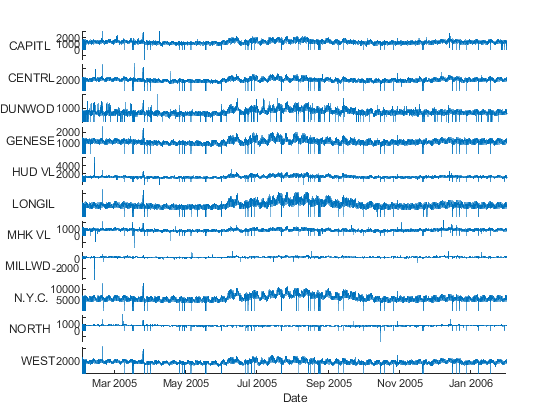

stackedplot(nyisoUnstack, 'XVariable', 'Date');

## Convert to a `timetable`

Since we're working with time stamped data, let's convert the table into a timetable, which has a large set of tools for working with time based data.  We'll see the data aren't regularly timestamped.

nyisott = table2timetable(nyisoUnstack);
isregular(nyisott)

ans = logical
   0


## Select region to clean

In nearly all real-world applications, each signal must be cleaned individually. Even if in the end the same settings can be used for all signals, this should never be assumed. Here we will focus on one particular region. You can pick which region to focus on from the drop down control. Note that some of the plots below are zoomed to focus on interesting features in the DUNWOD region.

region = "DUNWOD";
cleanSignal = nyisott(:, region);
cleanSignal.Properties.VariableNames = "Load";

## Visualize selected region

A closer look at the raw data for this region gives a better sense of the problems to be addressed.

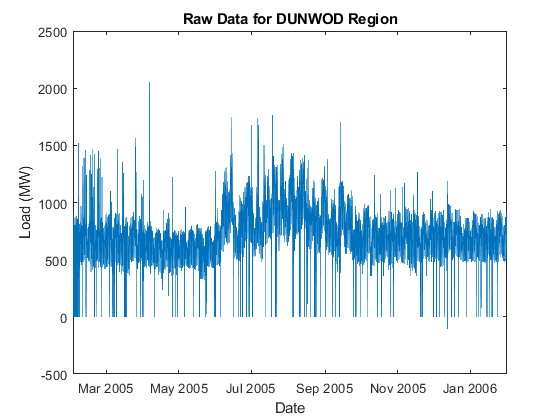

figure
plot(cleanSignal.Date, cleanSignal.Load)
xlabel('Date')
ylabel('Load (MW)')
title("Raw Data for " + region + " Region")

## Remove zero values and replace with estimate

We know that the zero values can't be correct, so let's identify them and replace them with an interpolated value. For the DUNWOD region, options such as linear and pchip work well, but notice that a spline does not work well. The `Clean Missing Data` Live Editor Task below allows us to quickly evaluate these different options and see their effects on the data.

cleanSignal = standardizeMissing(cleanSignal, 0);

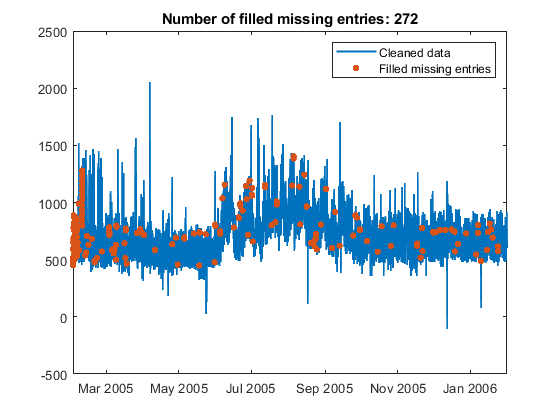

% Fill missing data
[cleanMissing,missingIndices] = fillmissing(cleanSignal.Load,'linear',...
    'SamplePoints',cleanSignal.Date);

% Visualize results
clf
plot(cleanSignal.Date,cleanMissing,'Color',[0 114 189]/255,'LineWidth',1.5,...
    'DisplayName','Cleaned data')
hold on

% Plot filled missing entries
plot(cleanSignal.Date(missingIndices),cleanMissing(missingIndices),'.',...
    'MarkerSize',12,'Color',[217 83 25]/255,...
    'DisplayName','Filled missing entries')
title(['Number of filled missing entries: ' num2str(nnz(missingIndices))])

hold off
legend

clear missingIndices
cleanSignal.Load = cleanMissing;

## Clean outliers

We still have the large spikes in our data. Just from the sensor data we cannot tell what caused these spikes. They could be valid values accurately capturing strange behavior in the system, or could be bad values caused by something like malfunctioning sensors or data corruption. In any case the spikes do not look normal. 

There are many interesting analyses we might do with such spikes, but in this case we want to create a model to understand normal behavior, so we will treat the spikes as outliers and attempt to identify and remove them. There are many ways to identify outliers; in this case we will use the the `Clean Outlier Data `Live Editor Task. Notice how changing the detection method from something like Moving Median to Moving Mean can significantly change what is catpured as an outlier.

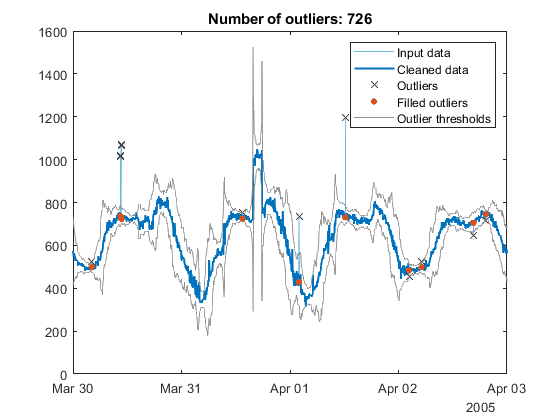

% Fill outliers
[cleanOutliers,outlierIndices,thresholdLow,thresholdHigh] = ...
    filloutliers(cleanSignal.Load,'linear','movmedian',hours(2),...
    'SamplePoints',cleanSignal.Date);

% Visualize results
clf
plot(cleanSignal.Date,cleanSignal.Load,'Color',[109 185 226]/255,...
    'DisplayName','Input data')
hold on
plot(cleanSignal.Date,cleanOutliers,'Color',[0 114 189]/255,'LineWidth',1.5,...
    'DisplayName','Cleaned data')

% Plot outliers
plot(cleanSignal.Date(outlierIndices),cleanSignal.Load(outlierIndices),'x',...
    'Color',[64 64 64]/255,'DisplayName','Outliers')
title(['Number of outliers: ' num2str(nnz(outlierIndices))])

% Plot filled outliers
plot(cleanSignal.Date(outlierIndices),cleanOutliers(outlierIndices),'.',...
    'MarkerSize',12,'Color',[217 83 25]/255,'DisplayName','Filled outliers')

% Plot outlier thresholds
plot([cleanSignal.Date(:); missing; cleanSignal.Date(:)],...
    [thresholdHigh(:); missing; thresholdLow(:)],'Color',[145 145 145]/255,...
    'DisplayName','Outlier thresholds')

hold off
legend
clear outlierIndices thresholdLow thresholdHigh
xlim(datetime(2005, [3 4], [30 3], 0, 0, 0))

cleanSignal.Load = cleanOutliers;

## Smooth data

Most physical measurements contain some amount of noise. Here we smooth the signal so we can focus on modeling its behavior without overfitting to the noise in the data.

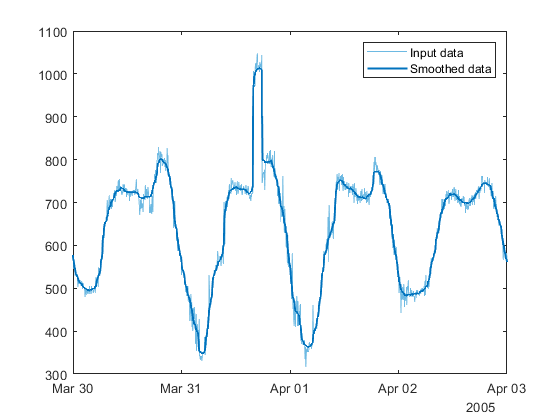

% Smooth input data
smoothedData = smoothdata(cleanSignal.Load,'movmedian',hours(2),...
    'SamplePoints',cleanSignal.Date);

% Visualize results
clf
plot(cleanSignal.Date,cleanSignal.Load,'Color',[109 185 226]/255,...
    'DisplayName','Input data')
hold on
plot(cleanSignal.Date,smoothedData,'Color',[0 114 189]/255,'LineWidth',1.5,...
    'DisplayName','Smoothed data')
hold off
legend
xlim(datetime(2005, [3 4], [30 3], 0, 0, 0))

cleanSignal.Load = smoothedData;

## Regularize time stamps

What is the distribution of sampling rates used?

summary(table(diff(cleanSignal.Date)))

Variables:

    Var1: 106162×1 duration

        Values:

            Min       00:00:01
            Median    00:05:00
            Max       01:05:00



The data is not regularly sampled. We will use `timetable` and `retime` to get the data onto a regular 5 minute interval.

nyiso = retime(cleanSignal, cleanSignal.Date(1):minutes(5):cleanSignal.Date(end), 'linear');

## Create `datastore` to access weather data

We have a large collection of weather data to work with. This public dataset is available from the [National Climatic Data Center](http://cdo.ncdc.noaa.gov/qclcd_ascii/). Let's see how much we have to work with. This section assumes you used Script4_WeatherDownload to download some data.

d = dir(fullfile(downloadfolder, "Weather", "HistWeather/*hourly.txt"));
assert(~isempty(d), 'You must run Script4_WeatherDownload.mlx to download some weather data before running this section.')

You must run Script4_WeatherDownload.mlx to download some weather data before running this section.

disp(compose("Total data on disk to search through: %.2f GB", sum([d.bytes])/(2^30)))

What does raw data file look like? Print out first five lines.

dbtype(fullfile(d(1).folder,d(1).name),'1:5')

A `datastore` can be used to easily access large collections of data.  We'll specify the location of the data, the variables we want, and their formats.

dsW = datastore(fullfile(downloadfolder, "Weather", "HistWeather/*hourly.txt"), ...
    'SelectedVariableNames', {'WBAN', 'Date', 'Time', 'DryBulbFarenheit', 'DewPointFarenheit'}, ...
    'SelectedFormats', {'%f', '%s', '%s', '%f', '%f'}, ...
    'ReadSize', 1e6, 'TextType', 'String', 'TreatAsMissing', {'M'});    
preview(dsW)

We also need a second table containing the WBAN stations we want to extract.  Here we specify them by ID.

stationList = [14735, 94790, 04725, 14733, 14748, 94745, 04781, 94789, 14732, ...
    94761, 54746, 64776, 14757, 14768, 14714, 14771, 64775]';

## Use `Tall` arrays to process big data

`Tall` arrays are made to handle big data and can seamlessly spill over to disk if needed. This allows us to process arbitrarily large out-of-memory data using MATLAB code very similar to how we would regularly write it for in-memory data. MATLAB waits to evaluate `Tall` arrays until they are either gathered to memory or written to disk so that it can determine the most optimal way to process the out-of-memory data. The `tall` arrays can be processed serially on a single machine, in parallel on a single machine, or in parallel on a traditional HPC center or Spark cluster.

Let's start by filtering out the unwanted stations. The `ismember` function will give us a logical index for which rows in the tall table contain the WBAN numbers we are interested in. We can then index into the tall array to extract just those rows. Note that MATLAB uses a delayed evaluation framework, so it is not running the full dataset now. However it will show us a preview, if possible, of the first few lines of results if we leave off the semicolon.

rawData = tall(dsW)
idxWBAN = ismember(rawData.WBAN, stationList);
weatherDataRaw = rawData(idxWBAN, :)

We have filtered out the unwanted stations, but the data is still not in the best format. Let's combine the `Date` and `Time` columns and convert them into a `datetime` variable. For convenience we can also combine the two temperature columns into a single Mx2 field in the table.

weatherDataRaw.Date = join([weatherDataRaw.Date, weatherDataRaw.Time], "");
weatherDataRaw.Date = datetime(weatherDataRaw.Date, 'InputFormat', 'yyyyMMddHHmm', 'TimeZone', 'America/New_York');
weatherDataRaw.Temperature = [weatherDataRaw.DryBulbFarenheit, weatherDataRaw.DewPointFarenheit];
weatherDataRaw(:, {'Time', 'DryBulbFarenheit', 'DewPointFarenheit'}) = []

All of this is being done with delayed evaluation using the tall array framework. So far MATLAB has not done a full scan through the dataset, it is only building up a queue of tall array commands to run. One way to trigger those commands to run on the full dataset is with the `gather` command. This tells MATLAB to process the full tall arrays and gather the result into local memory, which is useful when the final answer will fit into memory.

weatherData = gather(weatherDataRaw);

Once we have gathered the data into memory, it is a normal variable. Let's unstack and sort it and look at the first few values. As we can see, the data is reported about once per hour, but the different weather stations report at different times. We will need to go through the same process as with the energy data to retime and clean up this dataset. Since we've already seen that, let's skip ahead in the next section.

weatherData = unstack(weatherData, 'Temperature', 'WBAN', 'VariableNamingRule', "modify");
weatherData = sortrows(weatherData, 'Date');
head(weatherData, 12)

## Merge load and weather data sets

We can also do the same aggregate and cleaning for the weather data. Full examples are in Script4, Script5 and Script6. For brevity, we will now simply load the results of Scripts 1-6.

clearvars
load("nyiso_cleaned")
load("weather_cleaned")

We would like to join these two timetables together. Similar to the `join` command for regular tables, there is the `synchronize` command for timetables.

% Synchronize timetables
syncedData = synchronize(nyiso,weatherData,'intersection','fillwithmissing')
syncedData = timetable2table(syncedData);

## Modeling the load forecast on a zone

Now we're ready to start modeling our data so we can make forecasts. The rest of the script examines applying machine learning to the data from New York City. Start by pulling out the relevant data into a separate table so it's easier to work with.

modelData = syncedData(:, {'Date', 'N_Y_C_', 'KLGA'});

Change the table column names to be more general.

modelData.Properties.VariableNames(2:3) = {'Load', 'Temperature'};

## Create predictors

In order to build an accurate model, we need useful predictors to work with. A common technique with temporal predictors is to break them into their separate parts so they can be varied independently of each other.

modelData.Hour = modelData.Date.Hour;
modelData.Month = modelData.Date.Month;
modelData.Year = modelData.Date.Year;
modelData.DayOfWeek = weekday(modelData.Date);
modelData.isWeekend = isweekend(modelData.Date);

Pull the temperature and dew point apart into separate columns as expected by the machine learning techniques.

modelData.Temp = modelData.Temperature(:, 1);
modelData.DewPnt = modelData.Temperature(:, 2);
modelData.Temperature = [];

## Lagged predictors

The load data itself can be used as a predictor. We could use a traditional time series analysis, but a look at the autocorrelation will show an interesting pattern. The peaks in the autocorrelation at the 24 and 168 hour lags suggest use of lagged predictors of 1 and 7 days.

c = xcorr(modelData.Load, 200, 'coeff');
figure
plot(-200:200, c)
title('Autocorrelation in load data')
xlabel('Lag (Hours)')
ylabel('Correlation')

Create the prior day (24 hour) and prior week (168 hour) lag variables.

modelData.PriorDay = nan(height(modelData),1);
modelData.PriorDay(25:end) = modelData.Load(1:end-24);
modelData.PriorWeek = nan(height(modelData),1);
modelData.PriorWeek(169:end) = modelData.Load(1:end-168);

## Train different models using Regression Learner App

One of the most challenging parts of a machine learning workflow is that there is no way to know with certainty what modeling technique will work best on a particular dataset until you just try them out and see what happens. The Statstics and Machine Learning Toolbox has a pair of machine learning apps to make this iterative process much easier. In this case we will use the [Regression Learner App](matlab: regressionLearner) to try out different regression techniques. After opening the app, start a new session with the `modelData` variable and be sure to pick the Load column as the Response. After importing the data you can try out many different techniques.

## Split to training and testing

Here we split the data into training and testing sets based on the date. More sophisticated techniques such as cross validation are also available.  We will test against the year 2012.

idxtrain = modelData.Date < datetime('1-Jan-2012','TimeZone','America/New_York') | ...
    modelData.Date > datetime('31-Dec-2012','TimeZone','America/New_York');
modelDataTrain = modelData(idxtrain,2:end);
modelDataTest = modelData(~idxtrain,2:end);

## Fit a Bagged Decision Tree

Solve the regression problem with a bagged decision tree. This model works by training many different decision trees using different subsets of the data and then using them as an ensemble through a processing know as 'bagging'. Since the training of each individual decision tree is independent, we can easily do this in parallel.

opts = statset('UseParallel', 'always');
mdl_tb = TreeBagger(30, modelDataTrain, 'Load', 'method', 'regression', 'options', opts);

A common metric for evaluating a load forecast is the mean absolute percent error.  It's formula is given by:


$$MAPE = \frac{1}{n}\Sigma_{t=1}^{n}\left|\frac{A_t-F_t}{A_t}\right|$$


Where $A_t$is the acutal measurement and $F_t$ is the forecast value.  Calculate the MAPE on the training and test data. The error rate on the test is fairly good considering the particular problem and the relativley low amount of effort that went into the model. However it is twice as high as the training data error rate, which suggests that our model may have over fit. Let's take a deeper look at how it did on the test data.

Ytrain_tb = predict(mdl_tb, modelDataTrain);
Ytest_tb = predict(mdl_tb, modelDataTest);
disp(compose("Treebagger Training set MAPE: %0.2f", mape(modelDataTrain.Load, Ytrain_tb)*100));
disp(compose("Treebagger Test set MAPE: %0.2f", mape(modelDataTest.Load, Ytest_tb)*100));

## Further Validation

While our model may do well on average it could still be struggling in isolated cases, so let's look at exactly how it does on the test data. In the plot below the measured response is overlayed on top of the 24 hour ahead prediction.

If we zoom and pan in the plot, we can see that while the model is doing fairly well most of the time, there are some isolated cases where it struggles. A big one is around the end of October 2012. This was a result of the historic hurricane Sandy hitting the New York area, which caused widespread power outages and cancellations of school and work. Our model is not able to capture this, which should be expected. But what should we do with the data? This situation is such an extreme outlier, that it is probably best to remove it from the data set entirely. Doing so will lower our test error rate and give a more accurate account of how the model will do under non-hurricane conditions.

Other common areas where the model struggles are around the holidays. Holidays are big deviations from normal behavior, and our model currently has no way of knowing when they occur. We can capture this behavior by creating a new binary feature that contains if that time stamp was part of a holiday, yes or no. 

figure
t = tiledlayout(2, 1);
tt(1) = nexttile(t);
hold on
plot(modelData.Date(~idxtrain), Ytest_tb, 'DisplayName', 'Prediction');
plot(modelData.Date(~idxtrain), modelDataTest.Load, 'DisplayName', 'Answer');
hold off
legend show
ylabel('Load (MW)')
    
tt(2) = nexttile(t);
plot(modelData.Date(~idxtrain), modelDataTest.Load-Ytest_tb);
legend('Bagged Trees')
ylabel('Error (MW)')
linkaxes(tt, 'x')

*Copyright 2014-2020 The MathWorks, Inc.*